# Sp2n型量子群の表現を構築するための代数構造の多項式表示

## 動機

C_n型量子群のmodule algebraは非可換変数としては既に得られている。これを可換変数で表示したい。

そのために可換変数で積構造の微分演算子による表示を解析する。

C_2型は既に達成されているので、一般化を試みる。

quantum symplectic spaceの定義をする。

## Uq(sp_2n)-modalgの定義

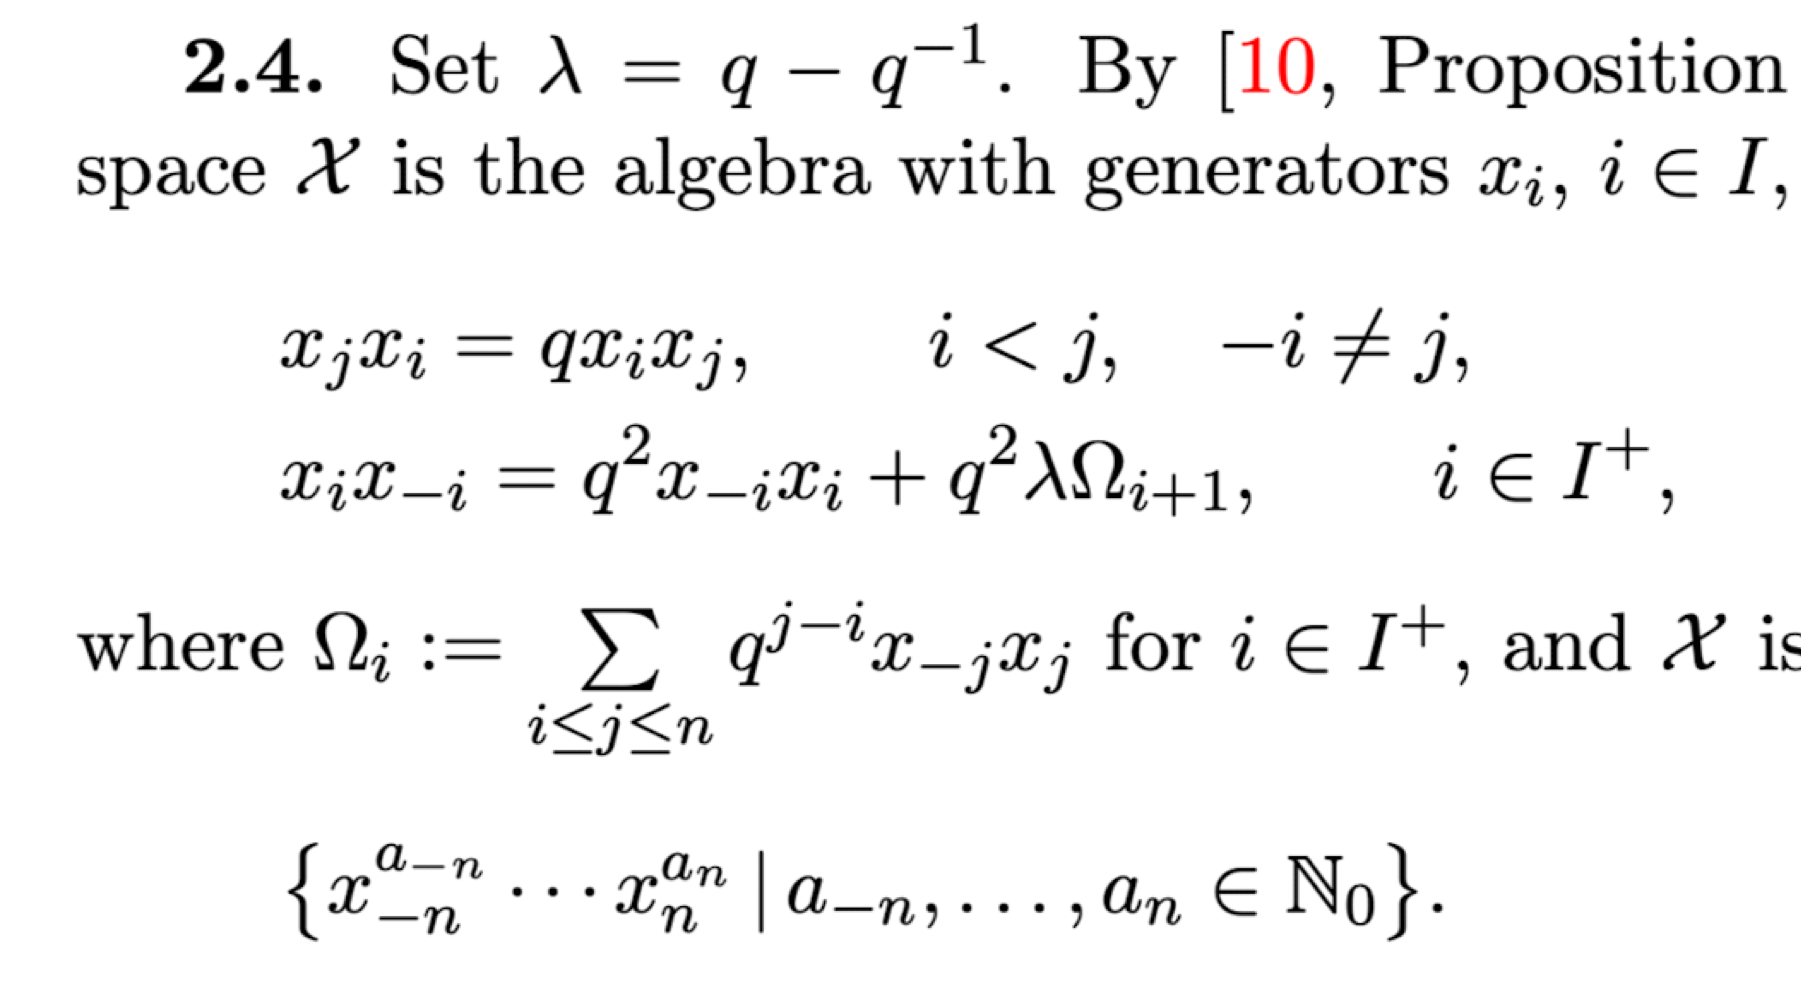

## Uqsp4modalgクラスによる規則性の発見

### strAlgによる計算

set(CR.H,'di',1)
[O,Xm2,Xm1,X1,X2]=strC2modalg.getGenerator();

Xm1*X2*Xm1*X1

ans =     coeff          base       
    _____    _________________
     q^2     x_m1 x_m1 x_1 x_2

X1^2*Xm1^2

ans =               coeff                    base       
    _________________________    _________________
    q^4*(q^2 - 1)^2*(q^2 + 1)    x_m2 x_m2 x_2 x_2
    q^5*(q^2 - 1)*(q^2 + 1)^2    x_m2 x_m1 x_1 x_2
    q^8                          x_m1 x_m1 x_1 x_1

X1^2*Xm1^5

ans =                  coeff                               base              
    _______________________________    ________________________________
    q^28 - q^20 - q^18 + q^10          x_m2 x_m2 x_m1 x_m1 x_m1 x_2 x_2
    -q^14*(- q^12 - q^10 + q^2 + 1)    x_m2 x_m1 x_m1 x_m1 x_m1 x_1 x_2
    q^20                               x_m1 x_m1 x_m1 x_m1 x_m1 x_1 x_1

### sympによる計算 symC2alg

ll=2;
syms q
qN=qNumS(q);
s=@simplify;
tau=qN.T;
QN=@qN.n;
v=rowfun(@(x)symC2modalg(1,x),table(eye(4)));
v=dictionary([-ll:-1,1:ll]',v.Var1);

v(1)^2*v(-1)^2

クラス strAlg には 'alignNum' という名前の Constant プロパティも静的メソッドもありません。
エラー:  *  (行 27)
            [i1,i2]=strAlg.alignNum(i1,i2);

v(1)*v(-1)
v(1)^2.*v(-1)^5

a1_=1;
a2_=3;
a3_=2;
a4_=1;
b1_=1;
b2_=4;
b3_=2;
b4_=1;
(Xm2^a1_*Xm1^a2_*X1^a3_*X2^a4_)*(Xm2^b1_*Xm1^b2_*X1^b3_*X2^b4_)+X1-X1

ans =               coeff                                              base                                
    _________________________    ____________________________________________________________________
    q^45 - q^39 - q^37 + q^31    x_m2 x_m2 x_m2 x_m2 x_m1 x_m1 x_m1 x_m1 x_m1 x_1 x_1 x_2 x_2 x_2 x_2
    q^39 + q^37 - q^31 - q^29    x_m2 x_m2 x_m2 x_m1 x_m1 x_m1 x_m1 x_m1 x_m1 x_1 x_1 x_1 x_2 x_2 x_2
    q^29                         x_m2 x_m2 x_m1 x_m1 x_m1 x_m1 x_m1 x_m1 x_m1 x_1 x_1 x_1 x_1 x_2 x_2

(v(-2)^a1_.*v(-1)^a2_.*v(1)^a3_.*v(2)^a4_)*(v(-2)^b1_*v(-1)^b2_.*v(1)^b3_.*v(2)^b4_)

ans =               coeff              x_m2    x_m1    x_1    x_2
    _________________________    ____    ____    ___    ___
    q^29                          2       7       4      2 
    q^39 + q^37 - q^31 - q^29     3       6       3      3 
    q^45 - q^39 - q^37 + q^31     4       5       2      4 

(v(-2)^a1_.*v(-1)^a2_.*v(1)^a3_.*v(2)^a4_)*(v(-2)^b1_.*v(-1)^b2_.*v(1)^b3_.*v(2)^b4_)

ans =               coeff              x_m2    x_m1    x_1    x_2
    _________________________    ____    ____    ___    ___
    q^29                          2       7       4      2 
    q^39 + q^37 - q^31 - q^29     3       6       3      3 
    q^45 - q^39 - q^37 + q^31     4       5       2      4 

## strCnmodalgを導入

一般のnに対して定義できるように拡張した。n=2で検証


[O,Xm2,Xm1,X1,X2]=strCnmodalg.getGenerator(2)

O =     coeff    base
    _____    ____
      0       1  

Xm2 =     coeff    base
    _____    ____
      1      x_m2

Xm1 =     coeff    base
    _____    ____
      1      x_m1

X1 =     coeff    base
    _____    ____
      1      x_1 

X2 =     coeff    base
    _____    ____
      1      x_2 

X1^2*Xm1^5

ans =                  coeff                               base              
    _______________________________    ________________________________
    q^28 - q^20 - q^18 + q^10          x_m2 x_m2 x_m1 x_m1 x_m1 x_2 x_2
    -q^14*(- q^12 - q^10 + q^2 + 1)    x_m2 x_m1 x_m1 x_m1 x_m1 x_1 x_2
    q^20                               x_m1 x_m1 x_m1 x_m1 x_m1 x_1 x_1

ll=3;
eval(sprintf("[O,%s]=strCnmodalg.getGenerator(%d);",join(["Xm"+(ll:-1:1) "X"+(1:ll)],","),ll));

X1^2*Xm1^2+0

ans =               coeff                    base       
    _________________________    _________________
    q^6*(q^2 - 1)^2*(q^2 + 1)    x_m3 x_m3 x_3 x_3
    q^5*(q^4 - 1)^2              x_m3 x_m2 x_2 x_3
    q^6*(q^2 - 1)*(q^2 + 1)^2    x_m3 x_m1 x_1 x_3
    q^4*(q^2 - 1)^2*(q^2 + 1)    x_m2 x_m2 x_2 x_2
    q^5*(q^2 - 1)*(q^2 + 1)^2    x_m2 x_m1 x_1 x_2
    q^8                          x_m1 x_m1 x_1 x_1